mu=pi*4e-7

mu = 1.2566e-06

Lc = 0.02

Lc = 0.0200

Rc = 0.0055

Rc = 0.0055

V=1.5

V = 1.5000

Rint = 0.247

Rint = 0.2470

rho = 1.77e-8

rho = 1.7700e-08

[layer, Dw]=meshgrid(1:1:25, 0.0002:0.00001:0.0016)

layer =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25
     1     2     3     4     5     6     7     8     9    10    11    12    13    14  

Dw =     0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002
    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002  


N=(Lc./(Dw+0.00002));
B=mu.*layer.*N.*V./(Lc.*(rho.*layer.*N.*2.*pi.*(Rc+length(layer, Dw) +Dw./2)./(pi.*(Dw./2).^2)+0.247))

B =     0.0042    0.0044    0.0045    0.0046    0.0046    0.0046    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047    0.0047
    0.0045    0.0049    0.0050    0.0050    0.0051    0.0051    0.0051    0.0051    0.0051    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052    0.0052
    0.0049    0.0053    0.0054    0.0055    0.0055    0.0056    0.0056    0.0056    0.0056    0.0056    0.0056    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057    0.0057
    0.0052    0.0057    0.0059    0.0060    0.0060    0.0061    0.0061    0.0061    0.0061    0.0061    0.0062    0.0062    0.0062    0.0062    0.0062    0.0062    0.0062    0.0062    0.0062    0.0062    0.0062    0.0062    0.0062    0.0062   

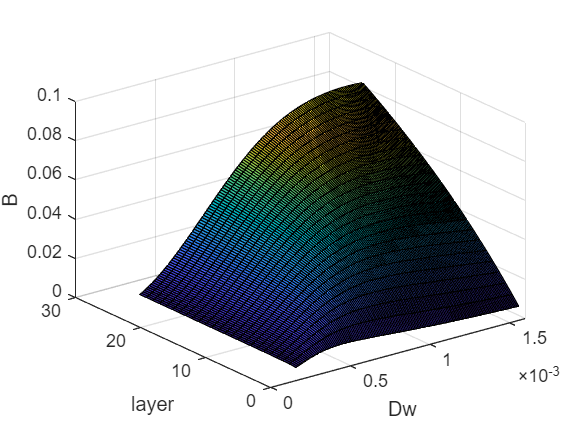


surf(Dw,layer,B)

xlabel("Dw")
ylabel("layer")
zlabel("B")



function total= length(lay, diam)
total = 0;
    for x=2:lay
       total = total + (x-1)*diam; 
    end
end

